# Entrenando redes neuronales

Debe contar con los Adds-on

- `Computer Vision Toolbox`

- `Image Processing Toolbox`

- `Computer Vision Toolbox Model for YOLO v4 Object Detection`

- `Deep Learning Toolbox`

## `Tutorial disponible en Matlab`

[https://la.mathworks.com/help/vision/ref/yolov4objectdetector.html](https://la.mathworks.com/help/vision/ref/yolov4objectdetector.html) 

[https://la.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v4-deep-learning.html](https://la.mathworks.com/help/deeplearning/ug/object-detection-using-yolo-v4-deep-learning.html) 

### Etiquetando imagenes: Image labeler 

[https://la.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html](https://la.mathworks.com/help/vision/ug/get-started-with-the-image-labeler.html) 

Image labeler es una aplicación en Matlab que nos ayuda a etiquetar imagenes, usulamente esta actividad consume bastantes recursos de tiempo.

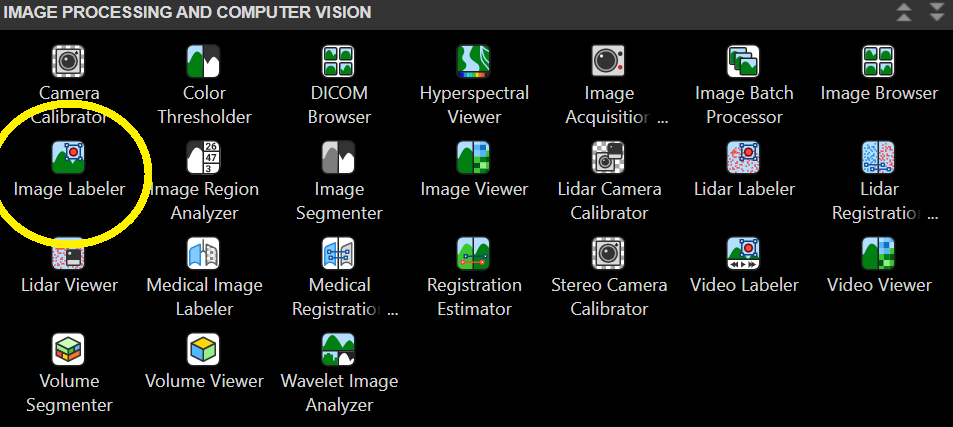

%Con la siguiente instrucción podrás también acceder al image labeler.
imageLabeler

1. Aquí importaremos las imagenes.

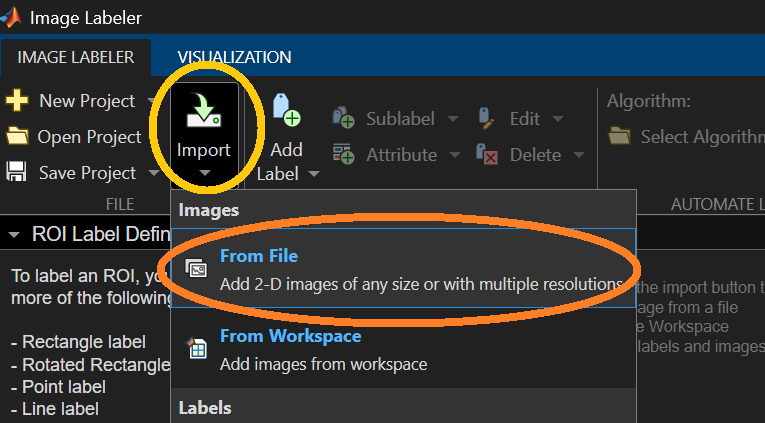

2. Agregamos etiquetas

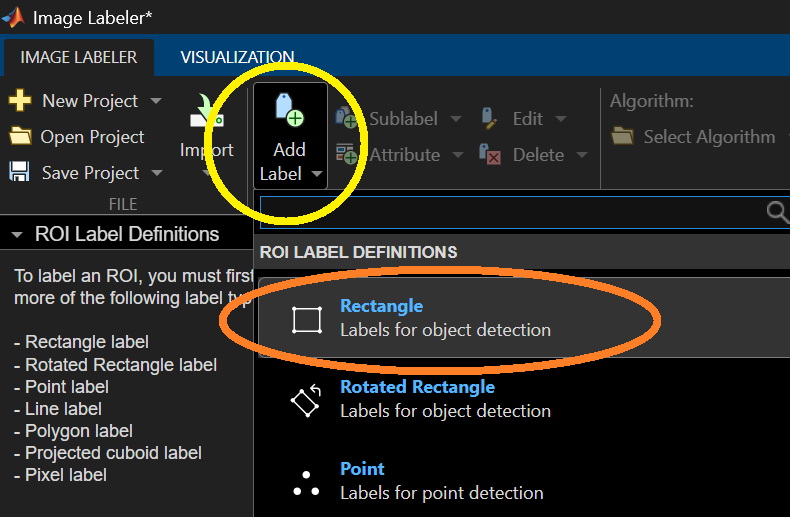

3. Seleccionamos imagenes

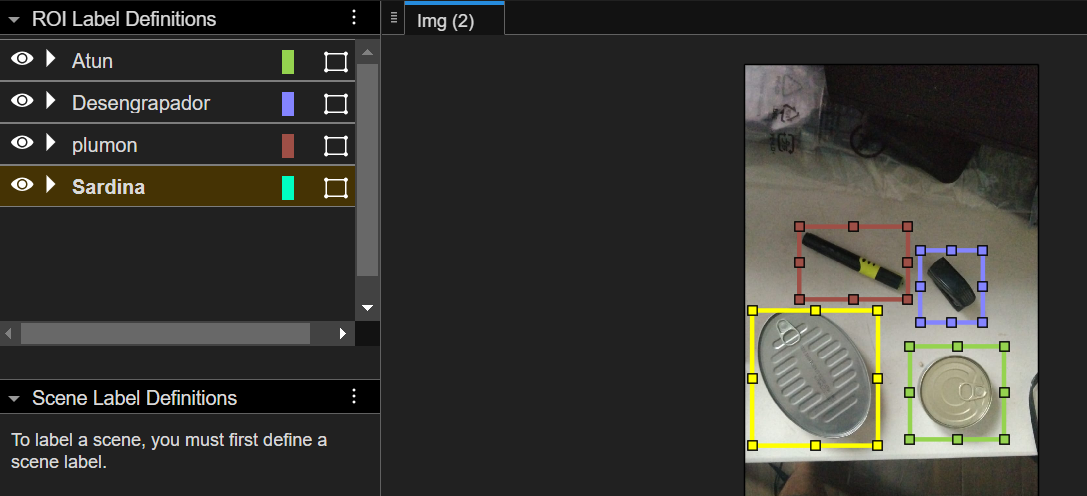

4. Exportamos tabla de direcciones y etiquetas.

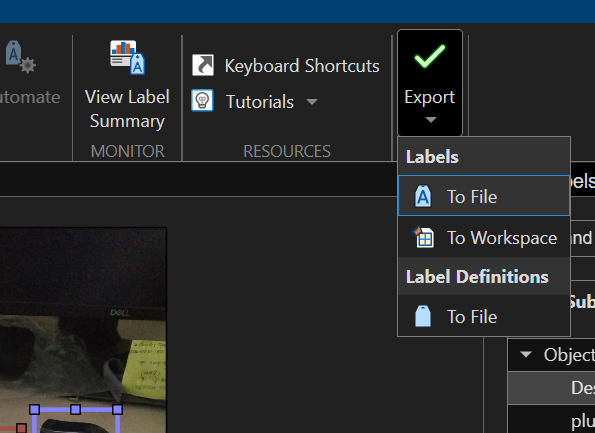

### Reentrenamiento de Red Neuronal

[https://la.mathworks.com/help/vision/ug/object-detection-using-yolov4-deep-learning.html](https://la.mathworks.com/help/vision/ug/object-detection-using-yolov4-deep-learning.html) 

Para entrenar la red neuronal, necesitamos.

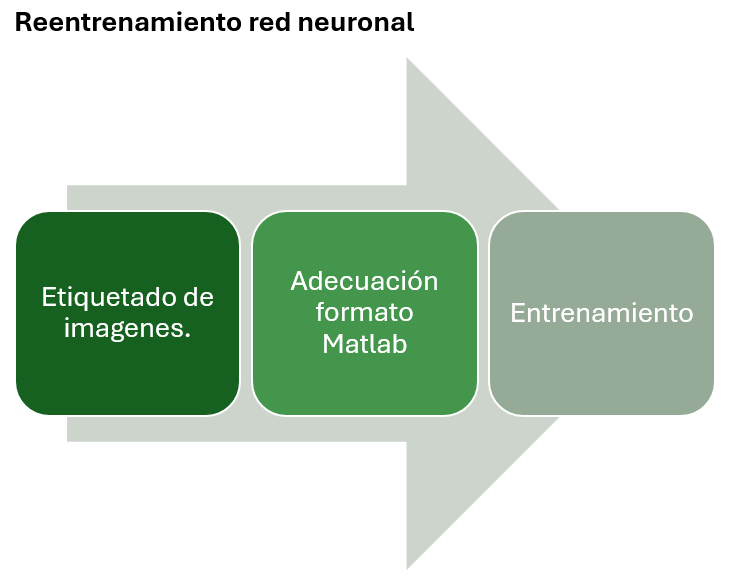

1. Registrar las direcciones de nuestras imagenes así como el contenido de cada imagen

%Aquí colocaras el nombre del archivo que exportaste de ImageLabeler
data = load("EtiquetasBotellasLatas.mat")
direccion = data.gTruth.DataSource.Source
cajas = data.gTruth.LabelData

mi_dataset = [direccion cajas]
mi_dataset.Properties.VariableNames(1) = {'imageFilename'}

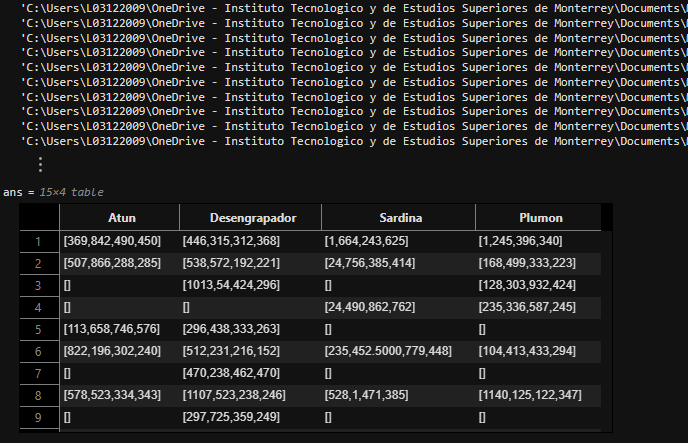

Fig. Información de ubicación de archivos y contenido de imagenes

2. Se generan bloques de entrenamiento, validación y prueba.

% Establecer la semilla del generador de números aleatorios para reproducibilidad
rng("default");

data = struct with fields:
    gTruth: [1×1 groundTruth]


direccion = 76×1 cell array
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB1.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB2.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB3.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB4.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB5.png' }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB6.png' }
    {'

% Se asume que personasDataset ya está cargado en el espacio de trabajo

cajas = 76×2 table
         Botella                 Lata       
    __________________    __________________

    {[234 40 110 127]}    {[15 269 163 138]}
    {[229 107 97 104]}    {2×4 double      }
    {[205 166 103 91]}    {2×4 double      }
    {[164 219 121 84]}    {[ 421 63 152 86]}
    {2×4 double      }    {[378 101 165 85]}
    {3×4 double      }    {[335 127 146 71]}
    {3×4 double      }    {[288 137 145 78]}
    {3×4 double      }    {[234 135 145 76]}
    {2×4 double      }    {[186 117 145 76]}
    {2×4 double      }    {[ 133 94 159 69]}
    {[  349 1 85 159]}    {[  95 54 154 76]}
    {[  318 1 98 115]}    {[   76 9 150 76]}
    {2×4 double      }    {2×4 double      }
    {2×4 double      }    {3×4 double      }
    {2×4 double      }    {2×4 double      }
    {2×4 double      }    {2×4 double      }



% Generar una permutación aleatoria de los índices de las filas del dataset

mi_dataset = 76×3 table
                                                                                Var1                                                                                     Botella                 Lata       
    ____________________________________________________________________________________________________________________________________________________________    __________________    __________________

    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB1.png' }    {[234 40 110 127]}    {[15 269 163 138]}
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB2.png' }    {[229 107 97 104]}    {2×4 double      }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnolo

shuffledIndices = randperm(height(mi_dataset));

mi_dataset = 76×3 table
                                                                           imageFilename                                                                                 Botella                 Lata       
    ____________________________________________________________________________________________________________________________________________________________    __________________    __________________

    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB1.png' }    {[234 40 110 127]}    {[15 269 163 138]}
    {'C:\Users\L03122009\OneDrive - Instituto Tecnologico y de Estudios Superiores de Monterrey\Documents\MATLAB\EntrenandoYolo\FotosGazeboRGB\imagenRGB2.png' }    {[229 107 97 104]}    {2×4 double      }
    {'C:\Users\L03122009\OneDrive - Instituto Tecnolo


% Calcular el número de datos para el conjunto de entrenamiento (60% del total)
idx = floor(0.8 * length(shuffledIndices));

% Seleccionar los índices para el conjunto de entrenamiento
trainingIdx = 1:idx;
trainingDataTbl = mi_dataset(shuffledIndices(trainingIdx), :);

% Calcular los índices para el conjunto de validación (10% del total)
validationIdx = idx + 1 : idx + 1 + floor(0.1 * length(shuffledIndices));
validationDataTbl = mi_dataset(shuffledIndices(validationIdx), :);

% Asignar los índices restantes al conjunto de prueba
testIdx = validationIdx(end) + 1 : length(shuffledIndices);
testDataTbl = mi_dataset(shuffledIndices(testIdx), :);

% Ahora, trainingDataTbl, validationDataTbl y testDataTbl contienen
% los datos divididos en entrenamiento (70%), validación (20%) y prueba (10%).

4. Creamos los paquetes para cargar las fotos durante el entrenamiento

lista = string(mi_dataset.Properties.VariableNames(2:end))

imdsTrain = imageDatastore(trainingDataTbl{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,lista));

imdsValidation = imageDatastore(validationDataTbl{:,"imageFilename"});
bldsValidation = boxLabelDatastore(validationDataTbl(:,lista));

imdsTest = imageDatastore(testDataTbl{:,"imageFilename"});
bldsTest = boxLabelDatastore(testDataTbl(:,lista));


5. Combinamos la información

trainingData = combine(imdsTrain,bldsTrain);

lista = 1×2 string array
    "Botella"    "Lata"


validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

6. Validamos información

data = read(trainingData);

I = data{1};
bbox = data{2};
label = data{3};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = insertObjectAnnotation(annotatedImage, "Rectangle", bbox, label, ...
    TextBoxOpacity=0.9, FontSize=18);
figure
imshow(annotatedImage)
%reset(trainingData)

7. Ajustamos y aumentamos el dataset

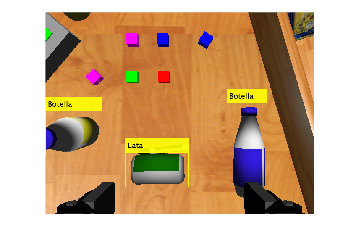

rng("default")
augmentedTrainingData = transform(trainingData,@augmentData);

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    augmentedData{k} = insertObjectAnnotation(augmentedData{k},"rectangle",data{2},data{3},TextBoxOpacity=0.9,FontSize=18);

    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

8. Precargamos la red neuronal

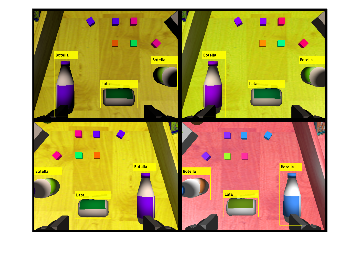

inputSize = [416 416 3]
lista
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors)

area = anchors(:, 1).*anchors(:,2)
[~,idx] = sort(area,"descend")

anchors = anchors(idx,:)
anchorBoxes = {anchors(1:3,:)
    anchors(4:6,:)}


detector = yolov4ObjectDetector("tiny-yolov4-coco",lista,anchorBoxes,InputSize=inputSize);

9. Entrenamos la red neuronal

options = trainingOptions("adam", ...

inputSize =    416   416     3


    GradientDecayFactor=0.9, ...          % Factor de decaimiento del gradiente (para optimización ADAM)

lista = 1×2 string array
    "Botella"    "Lata"


    SquaredGradientDecayFactor=0.999, ... % Factor de decaimiento del cuadrado del gradiente
    InitialLearnRate=0.001, ...           % Tasa de aprendizaje inicial
    LearnRateSchedule="none", ...         % Sin ajuste programado de la tasa de aprendizaje

anchors =     74    62
   132    61
    80    95
   201    59
    96    63
   121    91


meanIoU = 0.8275

    MiniBatchSize=10, ...                 % Tamaño del mini-lote (batch) por iteración
    L2Regularization=0.0005, ...          % Regularización L2 para evitar sobreajuste

area =         4588
        8052
        7600
       11859
        6048
       11011


    MaxEpochs=100, ...                     % Número máximo de épocas de entrenamiento

idx =      4
     6
     2
     3
     5
     1


    DispatchInBackground=true, ...        % Cargar datos en segundo plano para mejorar eficiencia
    ResetInputNormalization=true, ...     % Restablecer la normalización de entrada en cada iteración

anchors =    201    59
   121    91
   132    61
    80    95
    96    63
    74    62


    Shuffle="every-epoch", ...            % Mezclar los datos en cada época
    VerboseFrequency=4, ...              % Mostrar información de entrenamiento cada x iteraciones

anchorBoxes = 2×1 cell array
    {3×2 double}
    {3×2 double}


    ValidationFrequency=20, ...         % Evaluar con datos de validación cada 1000 iteraciones
    CheckpointPath=tempdir, ...           % Guardar puntos de control temporales
    ValidationData=validationData, ...    % Usar los datos de validación previamente definidos
    OutputNetwork="best-validation-loss"); % Guardar el modelo con la menor pérdida en validación+

    [detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);


10. Probamos la red neuronal.

%reset(testData);

data = read(testData);

Computing Input Normalization Statistics.

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* Botella
* Lata

Starting parallel pool (parpool) using the 'Processes' profile ...
23-Sep-2025 21:29:42: Job Queued. Waiting for parallel pool job with ID 3 to start ...
23-Sep-2025 21:30:42: Job Queued. Waiting for parallel pool job with ID 3 to start ...
Connected to parallel pool with 4 workers.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________
      1          1         00:00:41        0.001          2059            1869.4    
      1          4         00:01:11        0.001  

img = data{1};

[bboxes, scores, labels] = detect(detector, img)
img = insertObjectAnnotation(img,"rectangle",bboxes,labels);
figure
imshow(img)

function data = preprocessData(data,targetSize)
    for num = 1:size(data,1)
        I = data{num,1};
        imgSize = size(I);

bboxes = 3×4 single matrix
  445.8854  113.8026  113.9691  241.7408
    2.7515  136.2198  133.9070   73.0091
  225.1839  232.1672  126.2171   83.8022


scores = 3×1 single column vector
    0.9984
    0.9716
    0.9773


labels = 3×1 categorical array
     Botella 
     Botella 
     Lata 


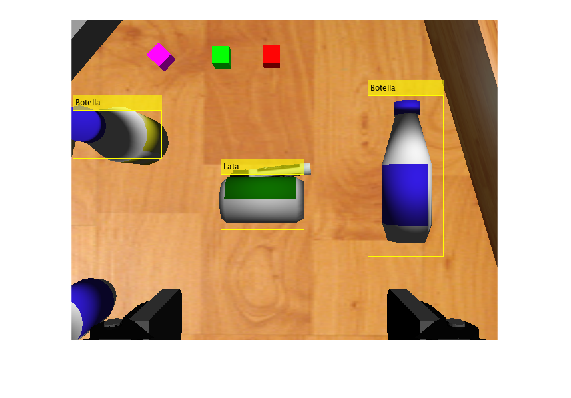

        bboxes = data{num,2};
        I = im2single(imresize(I,targetSize(1:2)));
        scale = targetSize(1:2)./imgSize(1:2);

        bboxes = bboxresize(bboxes,scale);
        data(num,1:2) = {I,bboxes};
    end
end

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
    data = cell(size(A));
    for num = 1:size(A,1)
        I = A{num,1};
        bboxes = A{num,2};
        labels = A{num,3};
        sz = size(I);

        if numel(sz) == 3 && sz(3) == 3
            I = jitterColorHSV(I,...
                contrast=0.0,...
                Hue=0.1,...
                Saturation=0.2,...
                Brightness=0.2);
        end
    
        % Randomly flip image.
        tform = randomAffine2d(XReflection=true,Scale=[1 1.1]);
        rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
        I = imwarp(I,tform,OutputView=rout);
    
        % Apply same transform to boxes.
        [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
        labels = labels(indices);
    
        % Return original data only when all boxes are removed by warping.
        if isempty(indices)
            data(num,:) = A(num,:);
        else
            data(num,:) = {I,bboxes,labels};
        end
    end
end